# 14 Linear Programming: Interior-Point Methods

#### Example

Solve the linear program

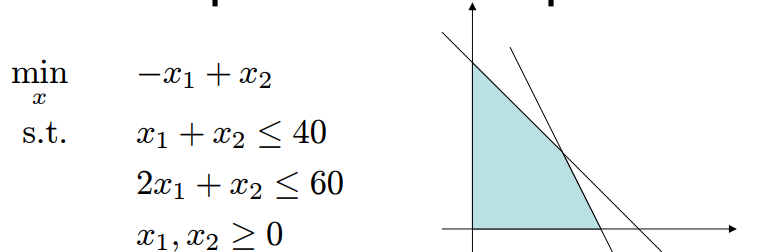

Write in standard form

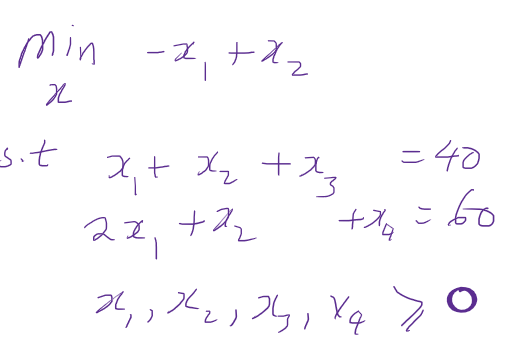

clearvars;
A = [1 1 1 0;2 1 0 1];
b = [40;60];
c=[-1;1;0;0];
[m,n] = size(A);
x=[5;30;5;10];
s = [0.1;2;0.1;0.1];
AA = [zeros(n,n) A' eye(n);A zeros(m,m+n);diag(s) zeros(n,m) diag(x)];


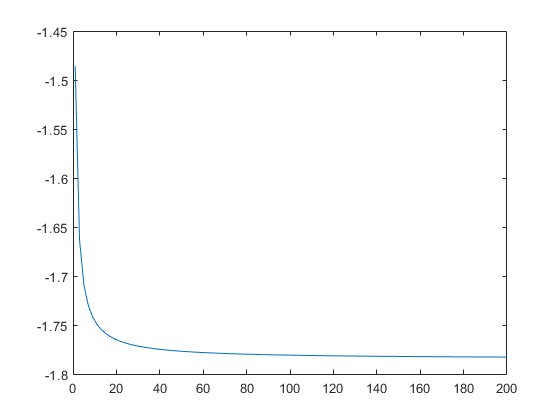

clearvars
syms tau real positive
syms y_1 real 
eqn1= @(t) (-1/t) == (1/(1+y_1))+(1/(3+y_1))+(1/(4+y_1));
sol = @(t) vpa(solve(eqn1(t), y_1));
x = linspace(1,200);
y = cell2mat(arrayfun(@(t) double(sol(t)),x,'UniformOutput',false));
plot(x,y)

% sol.y_1
% sol.parameters
% sol.conditions
% clearvars
% syms x_1 x_2 tau real positive
% eqn1= (-1/tau) == (1/(x_1+x_2-40))+(2/(2*x_1+x_2-60))+(1/x_1)
% eqn2= (1/tau) == (1/(x_1+x_2-40))+(1/(2*x_1+x_2-60))+(1/x_2)
% sol = solve([eqn1, eqn2], [x_1, x_2],"ReturnConditions",true)
% sol.x_1
